# Transfer Learning Using Voxel R-CNN for Lidar 3-D Object Detection

This example shows how to detect 3-D objects in lidar data by using transfer learning with a voxel region-based convolutional neural network (Voxel R-CNN) [1]. In this example, you:

- Configure a data set for training and testing of the Voxel R-CNN object detection network. You also perform data augmentation on the training data set to improve network efficiency.

- Compute anchor boxes from the training data to train the Voxel R-CNN object detection network.

- Create a pretrained Voxel R-CNN object detector as a `voxelRCNNObjectDetector` object, and perform transfer learning using the `trainVoxelRCNNObjectDetector` function.

## Prepare the Data

Note that the data set follows lidar sensor coordinate frames. For more information, see [Coordinate System in Lidar Toolbox](docid:lidar_gs#mw_353a3bc0-24a8-4025-ac67-92db32888d47). According to the sensor coordinate system, the positive *x*-axis must point forward from the ego vehicle, and the positive `y`-axis must point to the left of the ego vehicle for each point cloud. If your data set deviates from this orientation, you can adjust it by using the [`pctransform`](docid:vision_ref#bupmtw7-1) function for point clouds and the [`bboxwarp`](docid:vision_ref#mw_1da9aabf-0ba7-4abc-8ca9-1e9fcdc50771) function for bounding boxes.

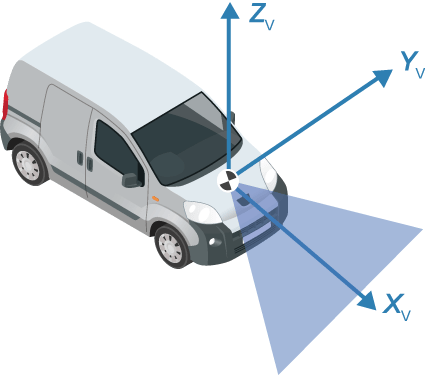

## Load Data

Create a datastore by using [`FileDatastore`](docid:matlab_ref#bvako8w) object that loads the PCD files from the specified path using the [`pcread`](docid:vision_ref#buphpf3-1) function.

Load ground truth data.

addpath(genpath("D:\OneDrive - MathWorks\Documents\SupportFileSystem\FlashLidar\PointClouds"));
gtPath = "D:\OneDrive - MathWorks\Documents\SupportFileSystem\FlashLidar\TrainingTable_Cuboids.mat";
bboxLabels = load(gtPath);
skipFrame = 100;
bboxTable = bboxLabels.CuboidTable(1:skipFrame:end,2:end);
fileTable = table2array(bboxLabels.CuboidTable(1:skipFrame:end,1));

Define a point cloud range that sets the boundaries of the region of interest within the point cloud data for detecting objects. The range specifies the minimum and maximum values along the *x*-, *y*-, and *z*-axes of the point cloud data. The Voxel R-CNN network focuses on the specified volume and ignores data points outside the range. This can help you optimize detection, performance by reducing the computational load and focusing on areas of interest. For more information on using point cloud ranges, see `voxelRCNNObjectDetector`.

pointCloudRange = [200 1160 -30 30 -30 30];
% Define the classes for object detection.
classNames = {'ATV', 'Jeep', 'PickupWhite', 'SUVBlack', 'VanWhite', 'Plane', 'SedanBlack', 'SportsCar'};
% Define colors for each class to plot bounding boxes.
colors = {'green','magenta','yellow', 'blue', 'white', 'red', 'cyan', 'black'};

Extract the bounding boxes and their associated labels that fall within the defined `pointCloudRange` by using `helperProcessGroundTruthData` helper function, defined at the end of this example. This step is crucial for evaluating the performance of the trained detector, as it helps assess how effectively the network identifies objects within the targeted region of interest it has been trained on.

bboxTable = helperProcessGroundTruthData(bboxTable,pointCloudRange);
[bboxTable, fileTable] = helperRemoveEmptyRows(bboxTable, fileTable);

To load 3-D bounding box information for the car, truck, and pedestrian object classes, create a box label datastore by using a [`boxLabelDatastore`](docid:vision_ref#mw_ea7fe152-be5c-4868-acb6-7c5d7fd40b93) object.

lds = fileDatastore(fileTable,"ReadFcn",@(x) pcread(x));
bds = boxLabelDatastore(bboxTable);

Combine the point cloud data and its ground truth information into a single datastore by using the [`combine`](docid:matlab_ref#mw_b02645f0-b121-4bee-a5c0-1c669ce05793) function.

cds = combine(lds,bds);

Create training and test sets from the data set. This example uses 80% of the data for training, and 20% data for testing.

rng(8)
totalElements = numpartitions(cds);

% Create a random permutation of indices.
shuffledIndices = randperm(totalElements);

% Specify split ratio, and calculate the number of training elements.
trainRatio = 0.8;
numTrainElements = round(totalElements*trainRatio);

% Determine indices for training and testing sets.
trainIndices = shuffledIndices(1:numTrainElements);
testIndices = shuffledIndices(numTrainElements+1:end);

% Create subsets of the datastore based on the calculated indices.
trainDs = subset(cds,trainIndices);
testDs = subset(cds,testIndices);

trainDsAug = transform(trainDs,@(x)helperRotateData(x));
testDsAug = transform(testDs,@(x)helperRotateData(x));
pointCloudRange = [100 1380 -24 24 -40 40];
voxelSize = [0.1 0.1 2];

Read and display a sample point cloud from the training data set, before augmentation, by using the `helperShowPointCloudWith3DBoxes` helper function, defined at the end of this example.

trainingSample = read(trainDsAug);
[ptCld,bboxes,labels] = deal(trainingSample{1},trainingSample{2},trainingSample{3});

helperShowPointCloudWith3DBoxes(ptCld,bboxes,labels,classNames,colors)

## **Create Voxel R-CNN Object Detector**

Estimate the anchor boxes from training data by using the `helperEstimate3DAnchorBoxesForVoxelRCNN` helper function, attached to this example as a supporting file.

anchorBoxes = helperEstimate3DAnchorBoxesForVoxelRCNN(trainDs,classNames);

Create a pretrained [`voxelRCNNObjectDetector`](docid:lidar_ref#mw_da18aca5-d763-46fc-8032-534b0a7ca0b3) object configured to perform transfer learning. For more information on the Voxel R-CNN network, see [Get Started with Voxel R-CNN](docid:lidar_ug#mw_53de191e-55d5-4336-b172-04b0e9f72bd7).

detector = voxelRCNNObjectDetector("none",classNames,anchorBoxes,PointCloudRange=pointCloudRange, VoxelSize=voxelSize); 

## Specify Training Options

Use the Adam optimization algorithm to train the network. Use the [`trainingOptions`](docid:nnet_ref#bu59f0q) function to specify the hyperparameters.

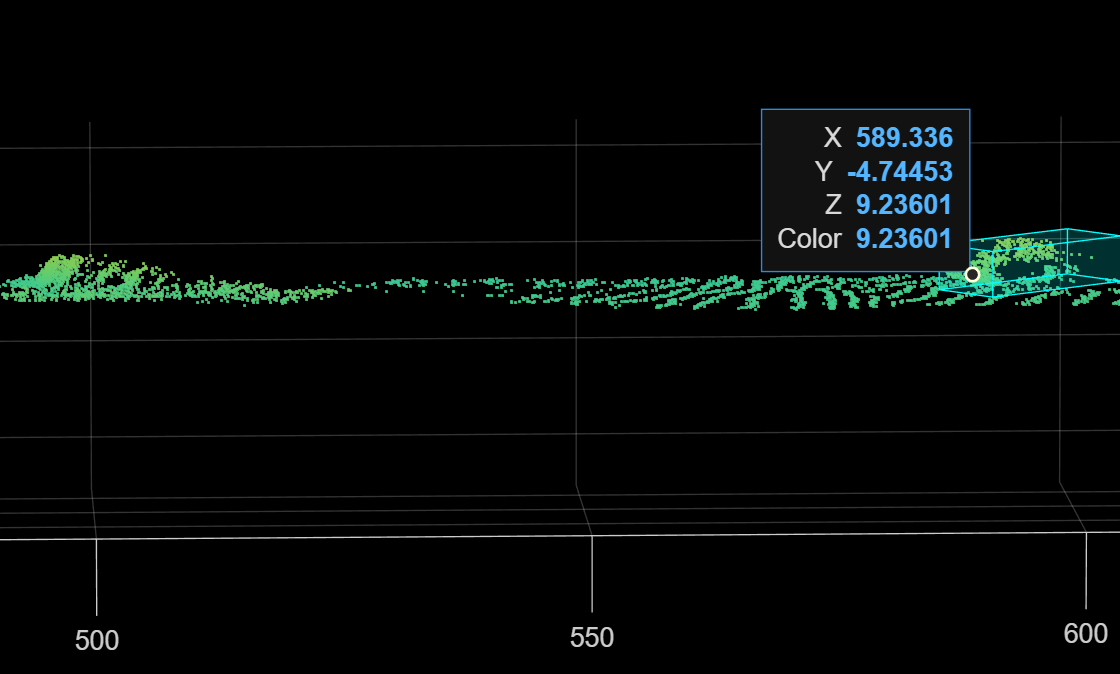

options = trainingOptions("adam", ...
    InitialLearnRate=0.0001, ...
    MiniBatchSize=3, ...
    MaxEpochs=1, ...
    PreprocessingEnvironment="serial", ...
    VerboseFrequency=20, ...
    CheckpointFrequency=1, ...

    CheckpointPath=tempdir, ...
    Plots="training-progress", ...
    Shuffle="every-epoch", ...
    L2Regularization=0.01);

**Note:** Reduce or increase the `miniBatchSize` value to control memory usage when training.

## Train Voxel R-CNN Object Detector

Use the [`trainVoxelRCNNObjectDetector`](docid:lidar_ref#mw_ea9c3cfb-e576-4c57-a71b-636fa24c581b) function to train the Voxel R-CNN object detector. 

To train the network, you must have Parallel Computing Toolbox™ and a CUDA® enabled NVIDIA® GPU. For more information, see [GPU Support by Release](docid:distcomp_ug#mw_57e04559-0b60-42d5-ad55-e77ec5f5865f).

[detector,info] = trainVoxelRCNNObjectDetector(trainDs,detector,options);

## Detect Objects in Point Cloud

Read a point cloud from the test sample, and run the trained detector to get detections, scores, and labels.

testData = read(testDsAug);
ptCloud = testData{1};
[bboxes,scores,labels] = detect(detector,ptCloud);
predTable = table(labels, scores, bboxes)

Overlay the object detections on the point cloud, and display the overlaid detections.

*************************************************************************
Processing data in minibatchqueue...

*************************************************************************
Data processing complete.

*************************************************************************
Training a VoxelRCNN object detector for the following classes:

* ATV
* Jeep
* PickupWhite
* SUVBlack
* VanWhite
* Plane
* SedanBlack
* SportsCar

 
    Epoch | Iteration | TimeElapsed | TrainingLoss |
    ________________________________________________
      1         20        30.502 sec     1020.5                  

      1         40        50.391 sec     117.46                  

      1         60        70.365 sec     6.6444                  

      1         80         90.1 sec      5.6846                  

      1         100       111.75 sec     6.708                  

      1         120       130.08 sec     3.6118                  

      1         140   

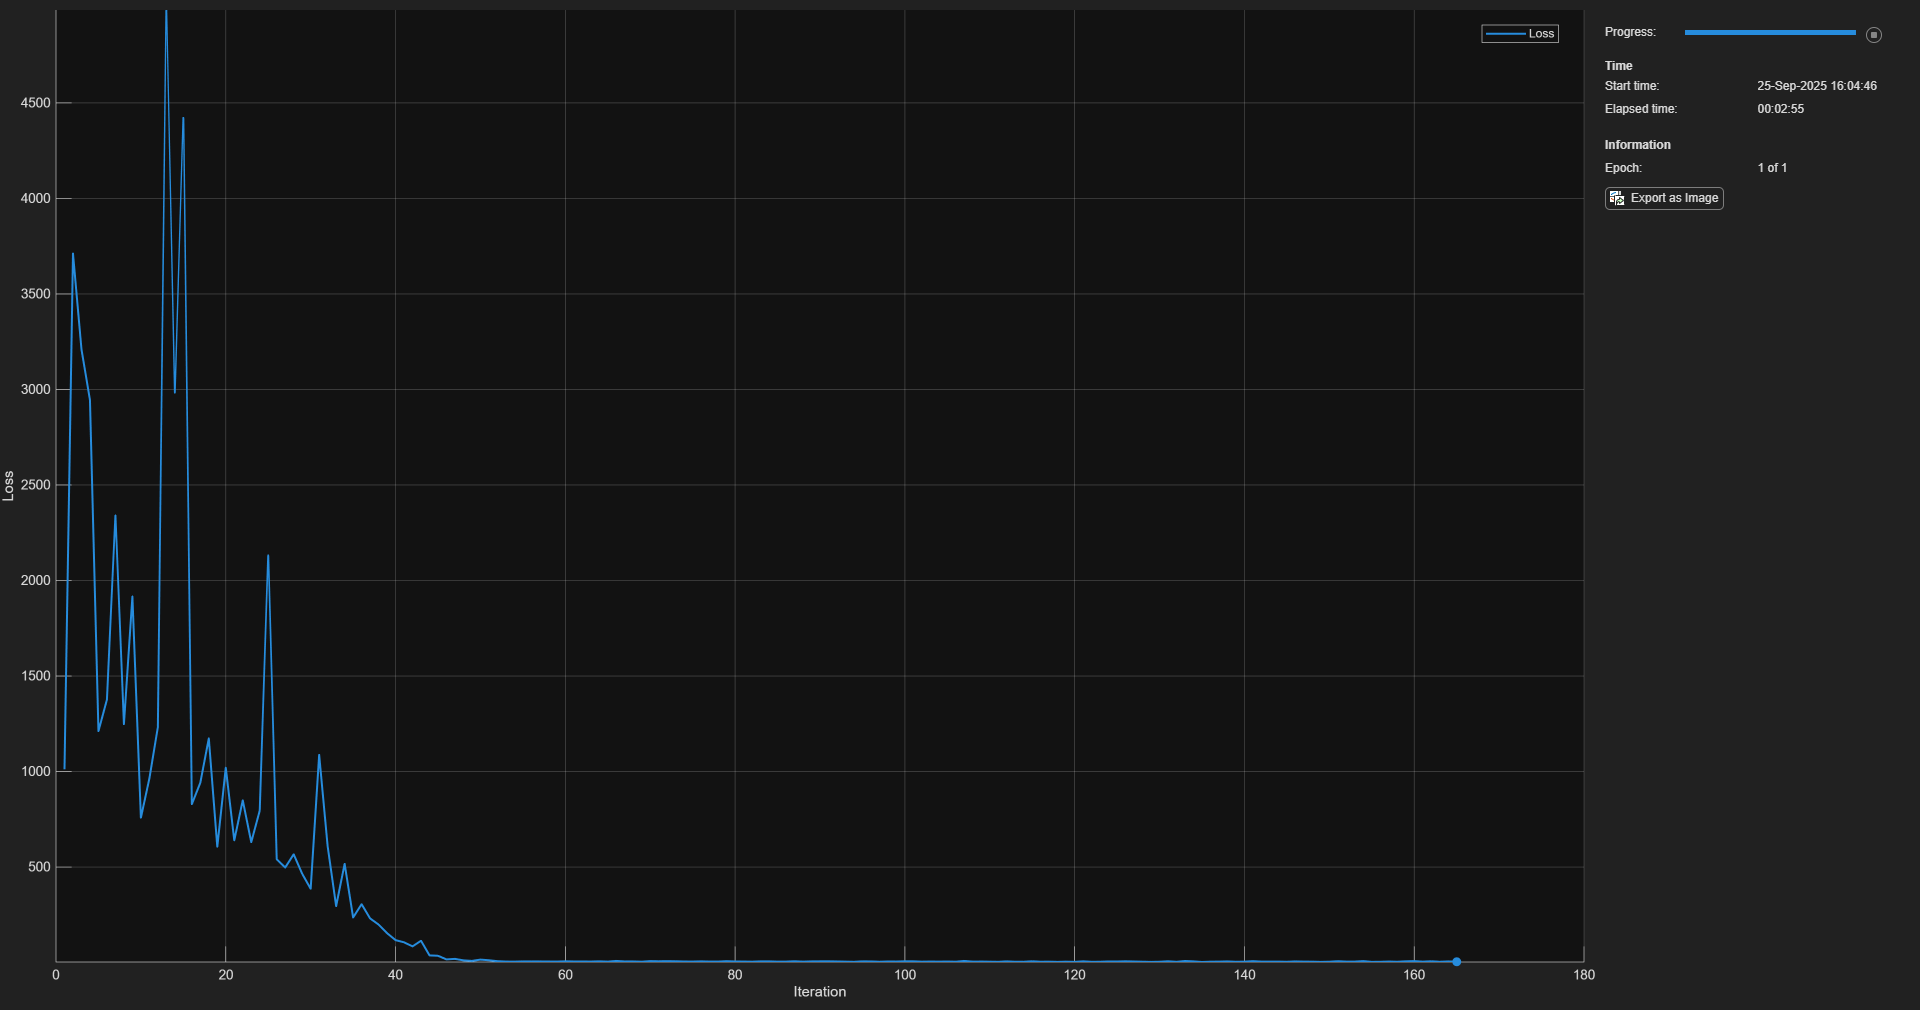


*************************************************************************
Detector training complete.
*************************************************************************



nPred = height(predTable);

Log = false(nPred,1);
Log(1:min(nPred, 5)) = true;
bboxesFil = bboxes(Log, :); scoresFil = scores(Log); labelsFil = labels(Log);
helperShowPointCloudWith3DBoxes(ptCloud,bboxesFil,labelsFil,classNames,colors)

## Evaluate Network

Run the detector on test data.

testPtClouds = testDs.UnderlyingDatastores{1,1};
detectionResults = detect(detector,testPtClouds,PredictedBoxType="rotated-rectangle");

Generate rotated rectangles of format Mx5 from the ground truth cuboid labels of format M-by-9 by using the `helperGetRotatedRectangle` helper function, defined at the end of this example.

testGrdTruth = testDs.UnderlyingDatastores{1,2};

predTable = 14×3 table
     labels      scores                                                 bboxes                                            
    _________    _______    ______________________________________________________________________________________________

    SportsCar    0.32253    957.06     13.235     4.5604     14.585     7.9323     3.9397          0          0     268.25
    SportsCar    0.32183    464.03      5.023     4.5282     14.608     8.0077     4.0043          0          0     268.16
    SportsCar    0.32166    526.33     9.8327     4.5583     14.755     8.0698     4.0034          0          0     268.66
    SportsCar     0.3214    577.55    -11.102     4.4921     14.594     8.0383     3.9992          0          0     268.53
    SportsCar    0.32052    933.02    -14.357     4.5075     14.517     7.9899     4.0045          0          0     268.64
    SportsCar

groundTruthData = transform(testGrdTruth,@(x)helperGetRotatedRectangle(x));

Evaluate the performance of the object detector by using the [`evaluateObjectDetection`](docid:vision_ref#mw_6aecf450-1718-4e91-b2cf-2972f639a177) function.

metrics = evaluateObjectDetection(detectionResults,groundTruthData,"AdditionalMetrics","AOS");
metrics.ClassMetrics   

The precision-recall (PR) curve highlights how precise a detector is at varying levels of recall. The ideal precision is 1 at all recall levels. 

Choose a class, extract the precision and recall metrics for that class, and then plot the precision and recall curves.

class = classNames(1);
precision = metrics.ClassMetrics{class,"Precision"};
recall = metrics.ClassMetrics{class,"Recall"};

figure
plot(recall{:}',precision{:}')
xlabel("Recall")
ylabel("Precision")
grid on


Running VoxelRCNN network.
--------------------------
* Processed 123 point clouds.

title(class + " Precision/Recall")

## Supporting Functions

The `helperShowPointCloudWith3DBoxes` function displays the point cloud alongside its associated bounding boxes, employing distinct colors for different classes to facilitate easy differentiation.

function helperShowPointCloudWith3DBoxes(ptCld,bboxes,labels,classNames,colors)
    % Validate the length of classNames and colors are the same.
    assert(numel(classNames)==numel(colors),"ClassNames and Colors must have the same number of elements.")
    
    % Get unique categories from labels.

ans = 8×8 table
                   NumObjects    APOverlapAvg        AP                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                              

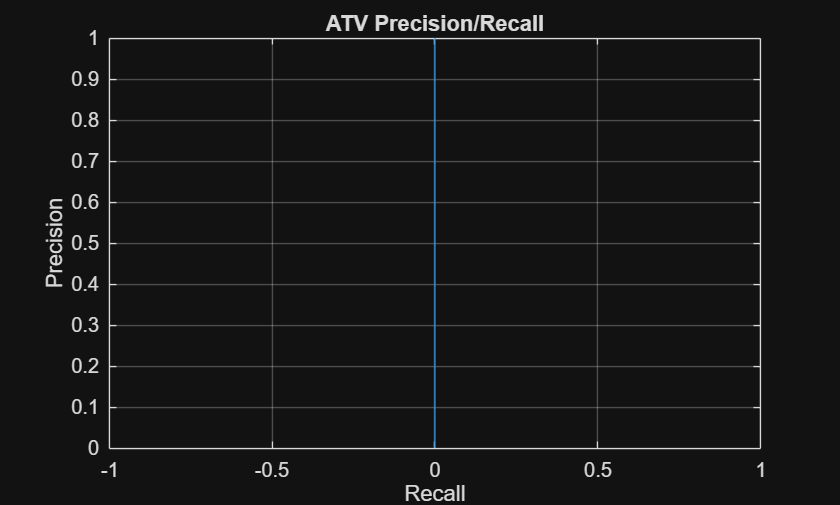

    uniqueCategories = categories(labels); 

    % Create a mapping from category to color.
    colorMap = containers.Map(uniqueCategories,colors); 
    labelColor = cell(size(labels));

    % Populate labelColor based on the mapping.
    for i = 1:length(labels)
        labelColor{i} = colorMap(char(labels(i)));
    end


    figure
    ax = pcshow(ptCld); 
    showShape("cuboid",bboxes,Parent=ax,Opacity=0.1, ...
        Color=labelColor,LineWidth=0.5)
    zoom(ax,5)
  
end

The `helperAugmentData` function applies these augmentations to the data:

-  Random scaling by 5%.

-  Random rotation along the *z*-axis from [—45, 45] degrees

-  Random translation by [0.2, 0.2, 0.1] meters along the *x*-, *y*-, and *z*-axes respectively.

function data = helperRotateData(data)
pc = data{1};
rotationAngles = [0 3 0];
translation = [0 0 40];
tform = affinetform3d(rigidtform3d(rotationAngles,translation));
pc = pctransform(pc,tform);

% Apply the same transformation to the boxes.
bbox = data{2};
outView = imref3d([10240, 640, 40],[-1e5 1e5],[-1e5 1e5],[-1e5 1e5]);
bbox= bboxwarp(bbox,tform, outView);
bbox(:,8) = 0;

data{1} = pc;
data{2} = bbox;
end

The `helperProcessGroundTruthData` function extracts bounding boxes for each label within the specified point cloud range.

function boxTable = helperProcessGroundTruthData(boxTable,pcRange)
for colIdx = 1:size(boxTable,2)
    % Apply the operation to each cell in the current column.
    boxTable{:,colIdx} = cellfun(@(x) helperGetBbox(x,pcRange),boxTable{:,colIdx},UniformOutput=false);
end
end

The helperGetBbox function extracts bounding boxes within the specified point cloud range.

function data = helperGetBbox(data,pcRange)
bbox = data;
if ~isempty(bbox)
    % Get index of bounding boxes that lie within pcRange.
    idx = (bbox(:,1) > pcRange(1)) & ...
        (bbox(:,1) < pcRange(2)) & ...
        (bbox(:,2) > pcRange(3)) & ...
        (bbox(:,2) < pcRange(4));
    data = bbox(idx,:);
end
end

The helperRemoveEmptyRows removes any row with no valid cuboids.

function [boxTable, fileTable] = helperRemoveEmptyRows(boxTable, fileTable)
%Eliminate all the rows with no cuboids
boxCell = table2cell(boxTable);
emptyCell = cellfun(@(x) isempty(x), boxCell, UniformOutput=false);
emptyMat = cell2mat(emptyCell);
emptyVec = all(emptyMat,2);
fileTable(emptyVec,:) = [];
boxTable(emptyVec,:) = [];
end

The `helperGetRotatedRectangle` function converts the bounding box format from M-by-9 (cuboid) to M-by-5 (rotated rectangle).

function data = helperGetRotatedRectangle(data)
bbox = data{1};
if ~isempty(bbox)
    % Convert bounding box format to rotated rectangle.
    data{1} = bbox(:,[1 2 4 5 9]);
end
end

### References

[1] Deng, Jiajun, Shaoshuai Shi, Peiwei Li, Wengang Zhou, Yanyong Zhang, and Houqiang Li. “Voxel R-CNN: Towards High Performance Voxel-Based 3D Object Detection.” *Proceedings of the AAAI Conference on Artificial Intelligence* 35, no. 2 (May 18, 2021): 1201–9. https://doi.org/10.1609/aaai.v35i2.16207.

[2] Hesai and Scale. PandaSet. [https://scale.com/open-datasets/pandaset](https://scale.com/open-datasets/pandaset).

*Copyright 2024 The MathWorks, Inc.*